# MPC tuning with Bayesian Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end
p = gcp();
fprintf('Using %d parallel workers', p.NumWorkers);

Using 1 parallel workers

## Define optimization variables

% var1 = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
% var2 = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');
% var3 = optimizableVariable('lambda', [1e-5, 1e-1], 'Transform', 'log');
% 
% optimization_variables = [var1, var2, var3];


var1 = optimizableVariable('lambda_z', [1e-5, 1e-1], 'Transform', 'log');
var2 = optimizableVariable('lambda_o', [1e-5, 1e-1], 'Transform', 'log');

optimization_variables = [var1, var2];
nVars = size(optimization_variables, 2);

## Objective function

Simulate MMCC + Induction Machine and calculate MPC mean cost

function cost = objective_function(x)
    try
        cost = MPC_simulate(x);
    catch
        cost = 10;
    end
end

## Bayesian optimization

Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |     lambda_z |     lambda_o |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       1 | Best   |          10 |      9.6229 |          10 |          10 |   1.2181e-05 |   2.5086e-05 |
|    2 |       1 | Accept |          10 |      4.6329 |          10 |          10 |     0.010697 |     0.052027 |
|    3 |       1 | Accept |          10 |       4.559 |          10 |          10 |   8.6927e-05 |   0.00063156 |
|    4 |       1 | Accept |          10 |      4.4621 |          10 |          10 |   0.00014747 |   0.00080786 |
|  

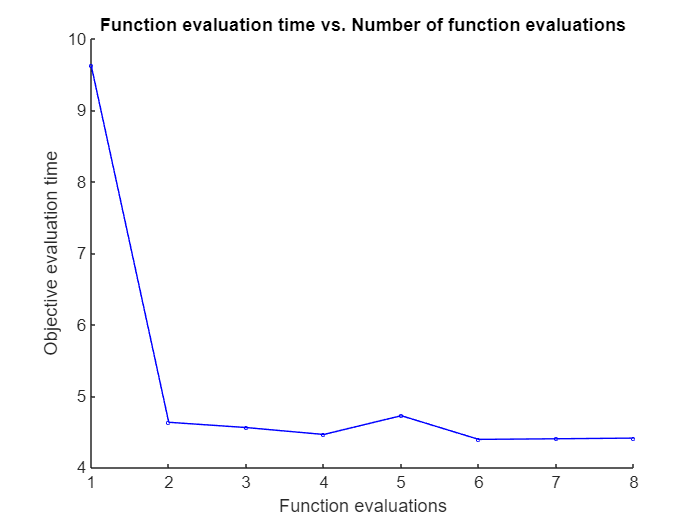

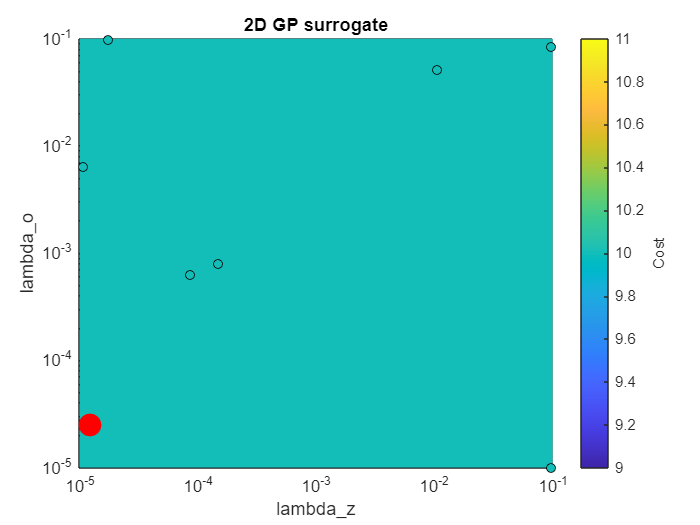

|    8 |       1 | Accept |          10 |      4.4115 |          10 |          10 |   1.0771e-05 |    0.0063865 |


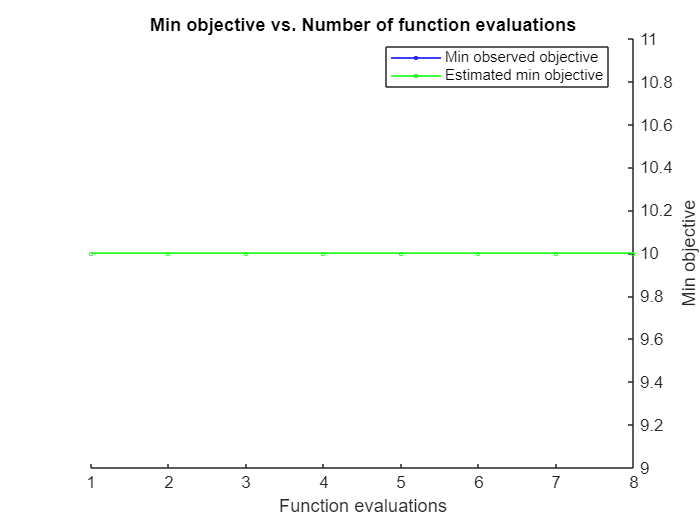

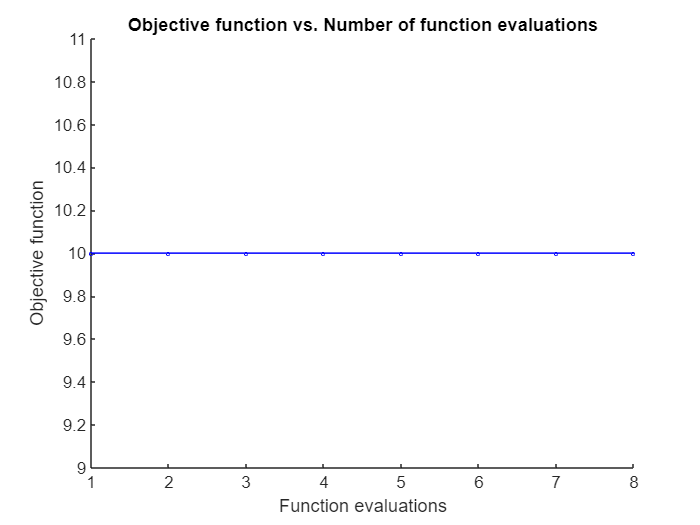

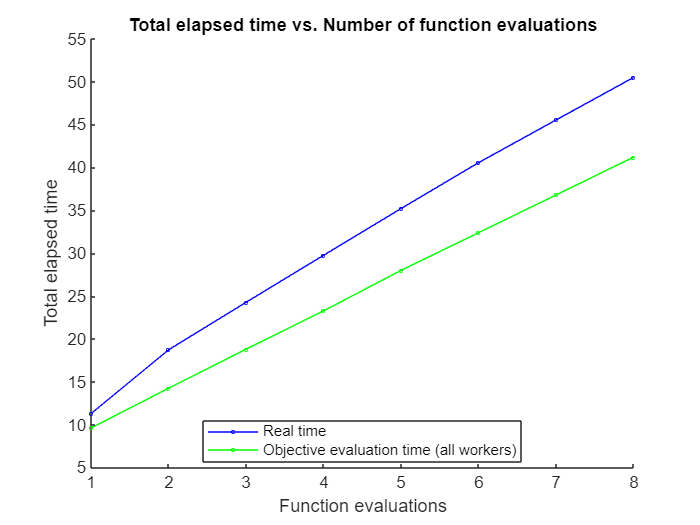

limits = vertcat(optimization_variables.Range);
lb = log10(limits(:, 1).');
ub = log10(limits(:, 2).');

NumSeedPoints = 2*p.NumWorkers;
Xlhs = lhsdesign(NumSeedPoints, nVars);
Xinit = 10 .^ bsxfun(@plus, lb, bsxfun(@times, (ub-lb), Xlhs));
Xinit = array2table(Xinit, 'VariableNames', {optimization_variables.Name});

results = bayesopt(@objective_function, optimization_variables, ...
    'MaxObjectiveEvaluations',   10*p.NumWorkers, ...
    'InitialX',                  Xinit, ...
    'AcquisitionFunctionName',   'expected-improvement-plus', ...
    'IsObjectiveDeterministic',  true, ...
    'UseParallel',               true, ...
    'Verbose',                   1, ...
    'PlotFcn',                   {@plotMinObjective, ...
                                  @plotObjective, ...
                                  @plotElapsedTime, ...
                                  @plotObjectiveEvaluationTime, ...
                                  @plotSurrogate} ...
);

## Reconstruct GP model

Retrieve bayesian optimization results

X = results.XTrace;
Y = results.ObjectiveTrace;
[Y, idx] = sort(Y, 'ascend'); % Sort by cost function
X = X(idx, :); 
varNames = {results.VariableDescriptions.Name};
sorted_Trace = [X table(Y, 'VariableNames', {'Cost'})]

Fit gaussian process

gp = fitrgp(X, Y, ...
    'Standardize', true, ...
    'KernelFunction', 'ardsquaredexponential');

## Plot GP

Plot fitted gaussian process

plotGP(gp, results, 'qF', 'qw')

## Sensitivity analysis

Global (trained kernel length scales)

A smaller lenght scale denotes a more important variable

lengthScales = gpGlobalSensitivity(gp)

Local (model gradient)

x_eval = table2array(X(1, :));
[gradMu, gradSigma2] = gpLocalSensitivity(gp, x_eval)